# Voxelwise Inference using Random Field Theory Practical

Author: Samuel Davenport

## Section 1: Introduction to Convolution Fields

This practical provides an introduction to voxelwise inference using convolution random fields AKA the correct way to use random field theory. You'll need to install the [RFTtoolbox](http://github.com/sjdavenport/RFTtoolbox) in order to run this correctly. See my website: [sjdavenport.github.io](http://sjdavenport.github.io) for more details.

% First you'll need to add all of the RFTtoolbox functions to your path
% by changing the following line:
folder_where_RFTtoolbox_is_saved = 'C:/Users/12SDa/davenpor/davenpor/Toolboxes/RFTtoolbox';
addpath(genpath(folder_where_RFTtoolbox_is_saved))

### Convolution Fields

Given a lattice $V$, let $X$ be a real valued random image on $V$ and let $K$ be a smoothing kernel, then the convolution field is defined as:


$$Y\left(s\right)=\sum_{l\;\in V} K\left(l-s\right)X\left(l\right)\ldotp$$


This is very easy to generate and we explore some examples below. Feel free to play with all of the examples to generate your own fields. 

#### 1D convolution fields

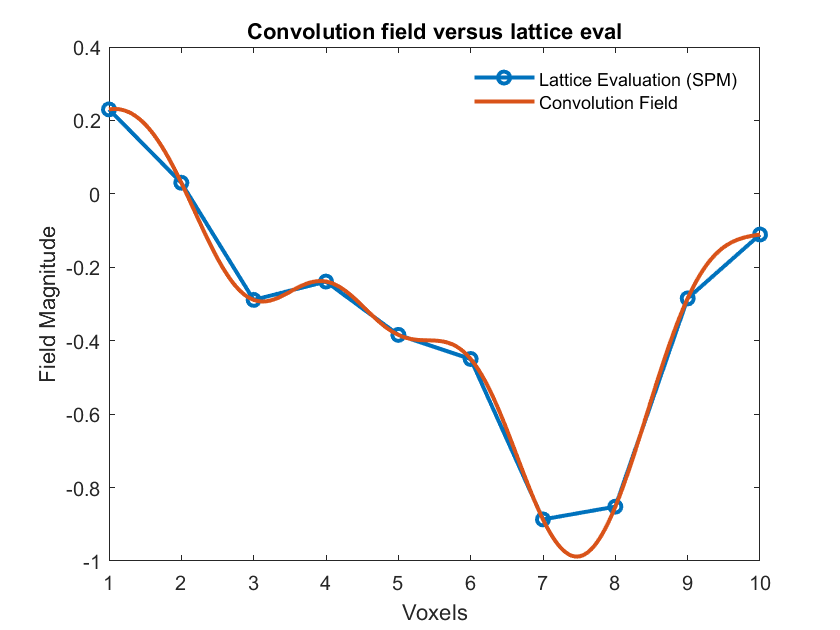

set(0, 'DefaultLineLineWidth', 2);
clf; nvox = 10; xvals = 1:nvox; spacing = 0.01;
xvals_fine = 1:spacing:nvox;
FWHM = 2;
lat_data = normrnd(0,1,1,nvox);
lattice_field = fconv(lat_data, FWHM);
convolution_field = convfield( lat_data, FWHM, spacing, 1);
plot(xvals, lattice_field, 'o-')
hold on
plot(xvals_fine,convolution_field)
title('Convolution field versus lattice eval')
xlabel('Voxels'); ylabel('Field Magnitude')
legend('Lattice Evaluation (SPM)', 'Convolution Field')

Notice that the maxima of the convolution field are higher than the lattice evaluation. This has lead to conservativeness when using voxelwise RFT without using convolution fields.

#### 2D convolution fields

Here we plot 2D convolution fields. Try expermenting with the spacing and FWHM parameters. 

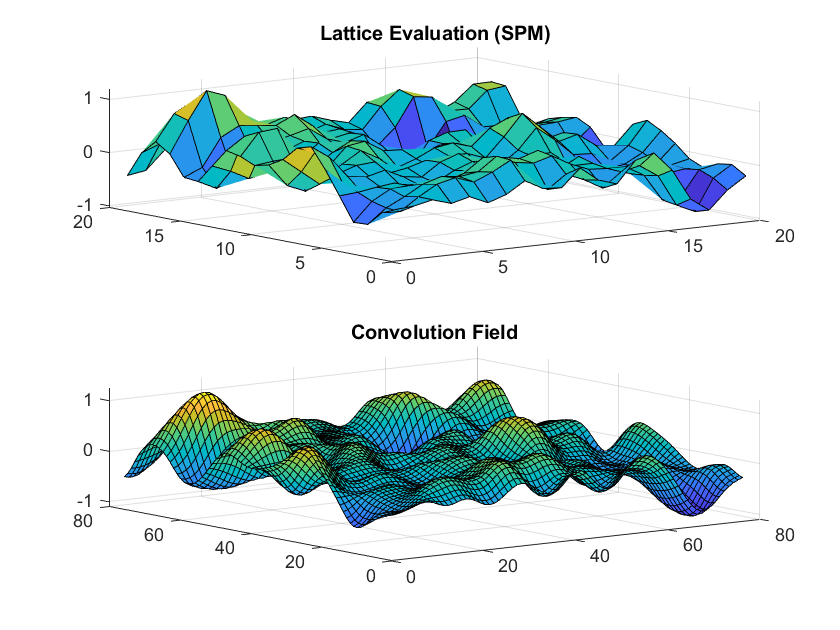

clf
Dim = [20,20]; D = length(Dim); spacing = 0.25; FWHM = 2;
lat_data = normrnd(0,1,Dim);
lattice_eval = fconv(lat_data, FWHM);
subplot(2,1,1)
surf(lattice_eval)
title('Lattice Evaluation (SPM)')
fine_data = convfield( lat_data, FWHM, spacing, D); %Convolution eval
subplot(2,1,2)
surf(fine_data)
title('Convolution Field')

#### Derivatives

Derivatives of convolution fields are easy to compute since$\nabla \;Y\left(s\right)=\sum_{l\;\in V} \nabla K\left(l-s\right)X\left(l\right)$where $\nabla \;$denotes the multivariate derivative.

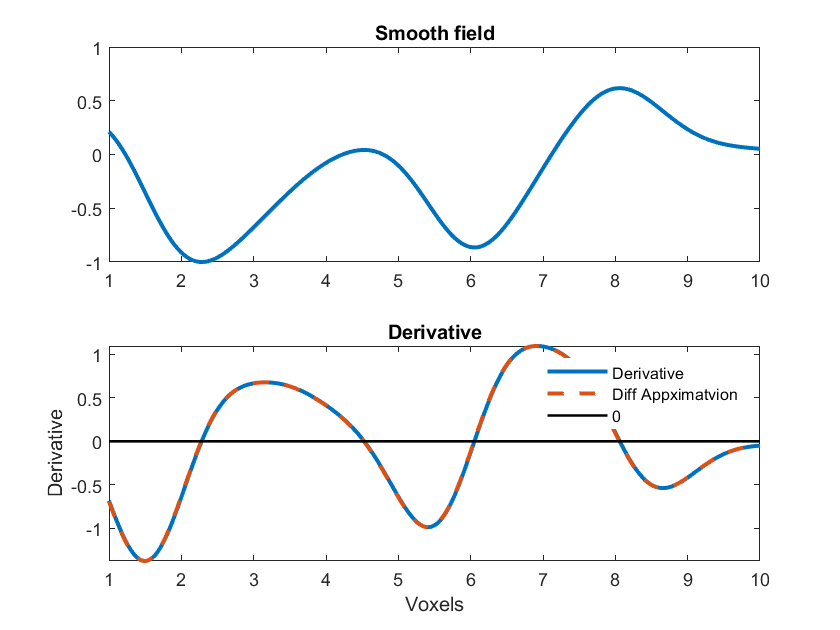

clf; nvox = 10; h = 0.01; FWHM = 1.5;
lat_data = normrnd(0,1,nvox,1);
[smoothedfield, xvals_vecs] = convfield( lat_data, FWHM, h, 1);
xvals_fine = xvals_vecs{1};
subplot(2,1,1)
plot(xvals_fine, smoothedfield)
title('Smooth field')
subplot(2,1,2)
derivtype = 1;
deriv1 = convfield( lat_data, FWHM, h, 1, derivtype );
deriv2 = diff(smoothedfield)/h;
plot(xvals_fine, deriv1)
hold on
plot(xvals_fine(1:end-1), deriv2, '--')
plot(xvals_fine, zeros(1, length(xvals_fine)), 'color', [0,0,0], 'LineWidth', 1.3)
title('Derivative')
legend('Derivative', 'Diff Appximatvion', '0')
xlabel('Voxels')
ylabel('Derivative')

Very importantly for RFT inference the zeros of the derivatives are the location of critical point, allowing the expected number of cirtical points to be found.

#### Comparing spm_smooth and fconv (Need SPM installed for this)

Smoothing in 3D is typically time consuming. In SPM this is typically done using SPM_smooth however this function is inefficient. A much faster implementation available in the toolbox is fconv.m. The following speed comparison shows that fconv is typically over 3-4 times as fast as spm_smooth. (This speed up is great in general but is particularly useful when calculating convolution fields.) Note that the truncation of the kernel is set to the same value for both. SPM scales badly with increased FWHM.

% You'll need SPM for this section, if you don't have it, you'll have to skip
% it and will need to comment it out.
addpath(genpath("your_spm_path")) %Change this to you spm path (or comment it out if you have already loaded SPM)

Dim = [100,100,100]; lat_data = normrnd(0,1,Dim);
FWHM = 6;
tic; fconv(lat_data, FWHM); toc

Elapsed time is 0.053650 seconds.


tic; smoothed_spm = zeros(Dim);
spm_smooth(lat_data, smoothed_spm, FWHM); toc

Elapsed time is 0.275711 seconds.


The following slices show that fconv gives the same results as spm_smooth. Note that by default spm doesn't use a Gaussian kernel (but instead uses the kernel given by spm_smoothkern) which is slightly different. The kernel can be specified as an option in fconv. (Note that below only lattice evaluations are shown not convolution fields.)

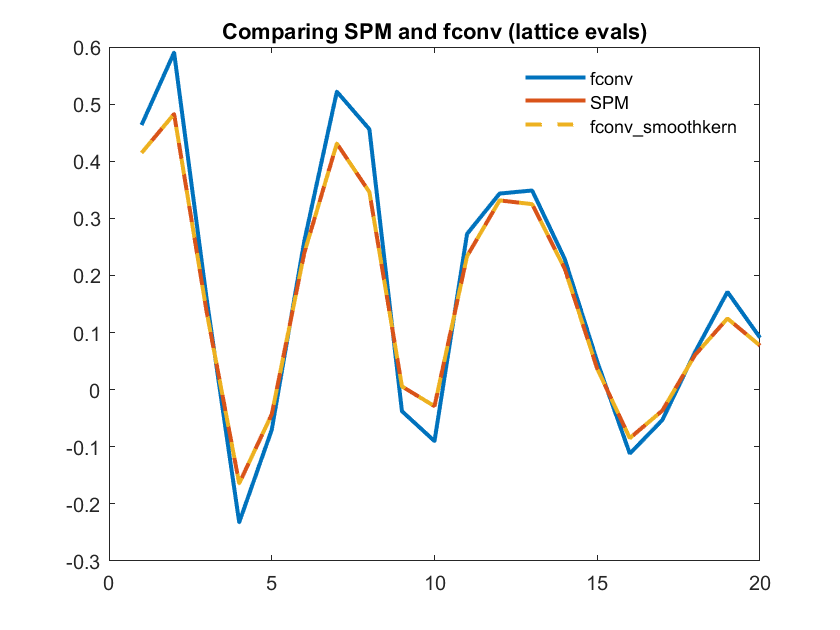

clf
Dim = [20,20,20]; lat_data = normrnd(0,1,Dim); halfDim = Dim(1)/2;
D = length(Dim); FWHM = 2;
smoothed_spm = zeros(Dim);
spm_smooth(lat_data, smoothed_spm, FWHM);
smoothed_fconv = fconv(lat_data, FWHM);
sigma = FWHM2sigma(FWHM); truncation = ceil(6*sigma);
smoothed_fconv_spmkern = fconv(lat_data, @(x) spm_smoothkern(FWHM, x), 3, truncation );
plot(1:Dim(1),smoothed_fconv(:,halfDim,halfDim))
hold on
plot(1:Dim(1),smoothed_spm(:,halfDim,halfDim))
plot(1:Dim(1),smoothed_fconv_spmkern(:,halfDim,halfDim), '--')
legend('fconv', 'SPM', 'fconv\_smoothkern')
title('Comparing SPM and fconv (lattice evals)')

To see the differences between the kernels see below. This difference is stark low FWHMs but goes away as FWHM inccreases. (Note that these kernels are evaluated on a lattice which is why the graph is not continuous.) This discrepancy is a problem for traditional RFT inference using SPM but is not an issue when using the LKC and convolution field approach which are valid for any twice differentiable kernel.

clf
FWHM = 2; truncation = 4*FWHM2sigma(FWHM)

truncation = 3.3973

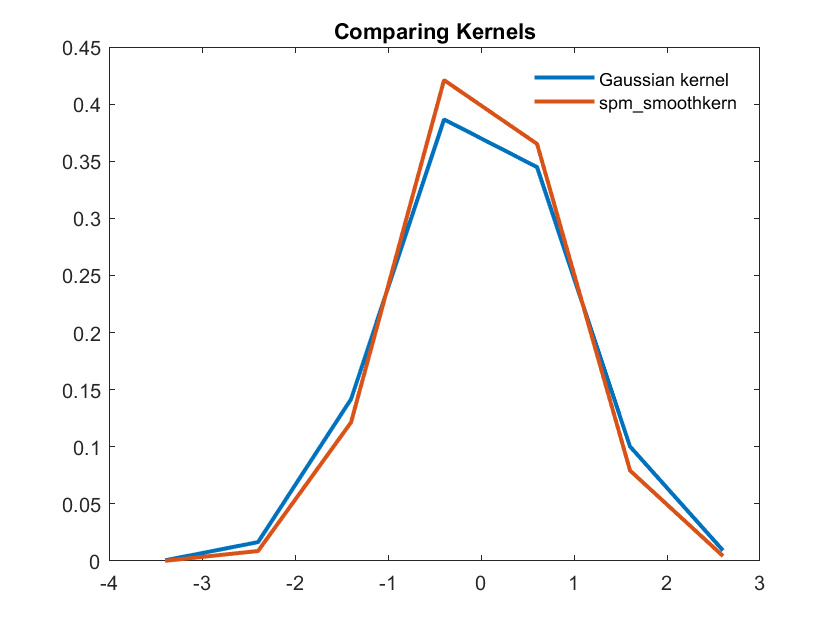

plot(-truncation:truncation, spm_smoothkern(FWHM, -truncation:truncation))
hold on
plot(-truncation:truncation, GkerMV(-truncation:truncation, FWHM))
legend('Gaussian kernel', 'spm\_smoothkern')
title('Comparing Kernels')

In order to generate multiple smooth fields and adjust for edge effects you can use noisegen.

clf; FWHM = 3; nsubj = 25; subj2use = 2;
noise = noisegen([50,50,50],nsubj, FWHM);
surf(noise(:,:,25,subj2use)); size(noise)

ans =     50    50    50    25


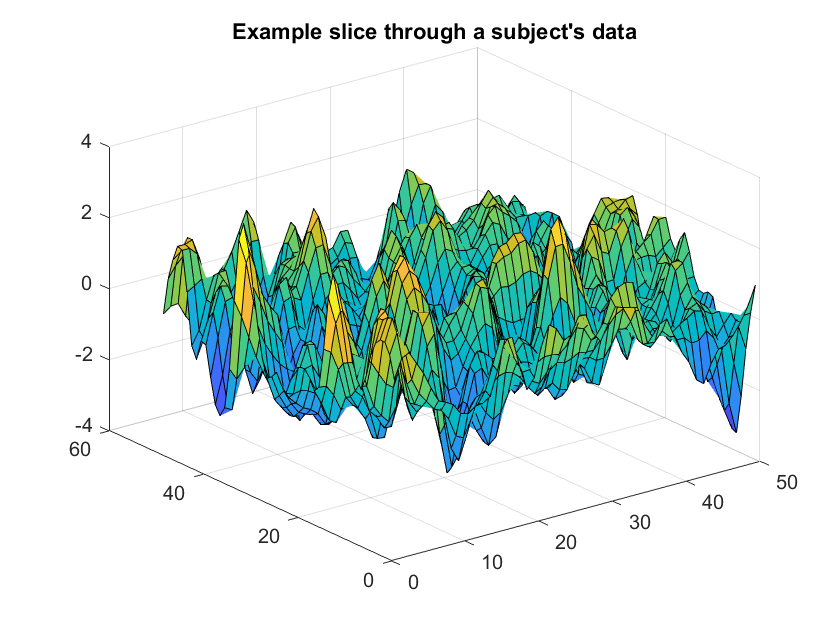

title('Example slice through a subject''s data')

### Convolution t-fields

In neuroimaging we are typically interested in testing and so we need to intrdouce more complicated fields. In particular we typically assume that the data from each subject is Gaussian and compute one-sample t-tests or F-tests at each voxel using. Given convolution fields: $Y_1 ,\ldotp \ldotp \ldotp ,Y_N$ from $N$ subjects, we define the convolution t-field to be:


$$T=\frac{\frac{1}{\sqrt{N}}\sum_{n=1}^N Y_n }{{\left(\frac{1}{N-1}{\sum_{n=1}^N \left(Y_n -\frac{1}{N}\sum_{n=1}^N Y_n \right)}^2 \right)}^{1/2} }$$


Similarly we can define a convolution F-field and more complicated examples.

#### 1D convolution t-fields

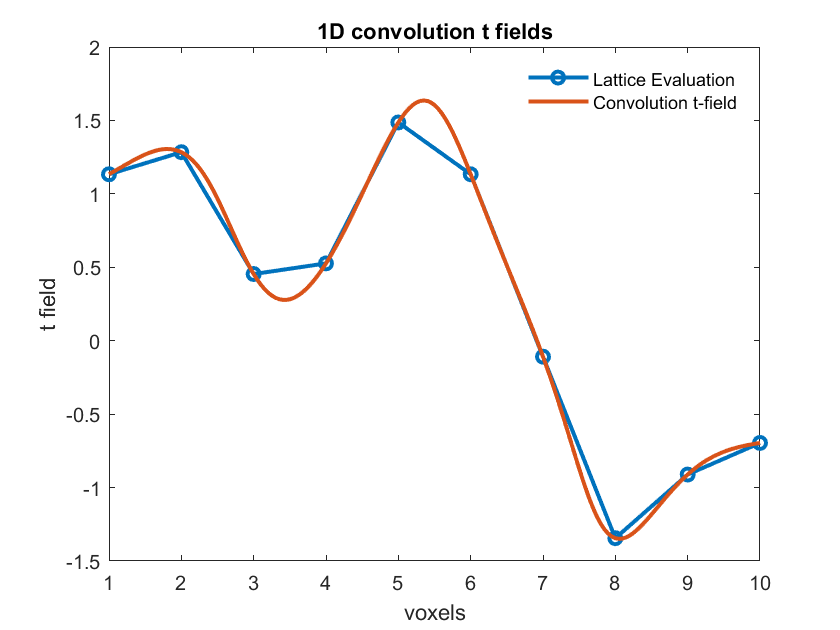

clf; nvox = 10; nsubj = 20; spacing = 0.05; FWHM = 2;
lat_data = normrnd(0,1,[nvox,nsubj]);
[tconvfield, xvals_vecs] = convfield_t(lat_data, FWHM, spacing);
xvals_fine = xvals_vecs{1};
lattice_tfield = convfield_t(lat_data, FWHM, 1);
plot(1:nvox, lattice_tfield, 'o-')
hold on
plot(xvals_fine, tconvfield)
title('1D convolution t fields')
legend('Lattice Evaluation', 'Convolution t-field')
xlabel('voxels')
ylabel('t field')

Similarly you can do the same in higher dimensions (see help convfield_t for details).

## Section 2: LKC and FWHM Estimation

NOTE: In order to run the 3D examples in this section you will need to have compiled the HPE C code. In you have had trouble with this please let me know and I'll try and help.

### Stationary LKC estimation

Under stationarity there are closed forms for the LKCs and these have been implemented in SPM. In particular


$$L_d =\sum_{F\in \Im_d } \left|F\right|\;{\textrm{det}\left(\Lambda_F \right)}^{1/2}$$


where the sum is over all faces of your domain of dimension d. As can be seen for the following examples under stationarity (and when the fields are large enough so that the edge effect doesn't impinge) SPM closely matches the LKCconv estimates. HPE is a good approximation but is less accurate without increased resolution. 

#### Estimating Lambda

If you smooth i.i.d Gaussian noise with a Gaussian kernel with smoothing parameter $\sigma \;$, then $\Lambda =\frac{\sigma^{-2} }{2}\;I$ (see e.g. Worsley 1992). Convolution estmates of $\Lambda \;$ can be estimated using Lambda_est.m. 

FWHM = 10; D = 1; Gker_param = FWHM2sigma(FWHM); nvox = 100; nsubj = 100;
Lambda_theory = Gker_param^(-2)/2

Lambda_theory = 0.0277

lat_data = normrnd(0,1,nvox,nsubj);
voxelwise_Lambda_estimates = Lambda_est( lat_data, FWHM, D );
Lambda_estimate = mean(voxelwise_Lambda_estimates(5:end-5))

Lambda_estimate = 0.0269

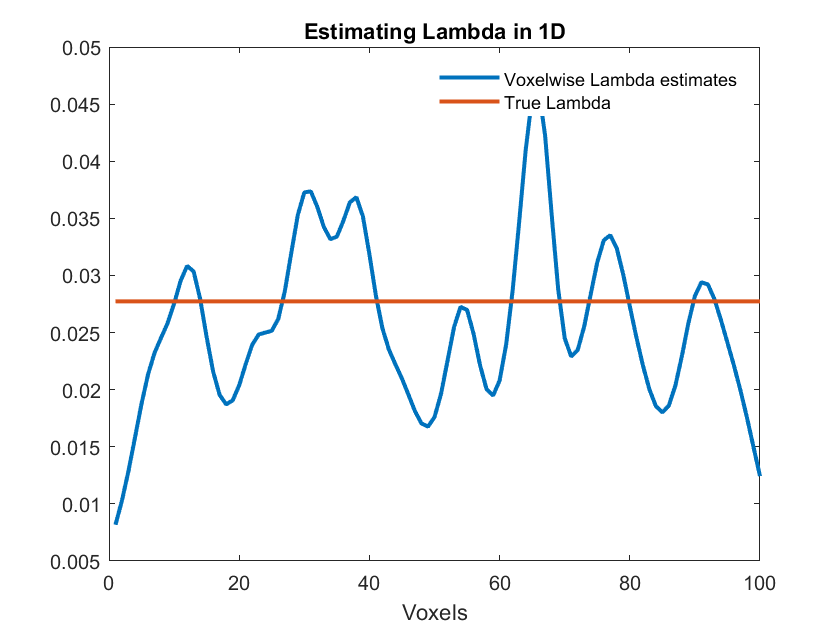

clf; plot(voxelwise_Lambda_estimates); hold on; plot(1:nvox, Lambda_theory*ones(1,nvox));
legend('Voxelwise Lambda estimates', 'True Lambda')
title('Estimating Lambda in 1D'); xlabel('Voxels');

Note that we have not accounted for edge effects in the plot (meaning that there are dicrepancies at the boundary).

#### 1D LKCs

In 1D (under stationarity). Note that to make things easier I haven't accounted for edge effects. Here $L_1 =T\Lambda^{1/2}$ where $T$ is the length of the line.

FWHM = 6; Gker_param = FWHM2sigma(FWHM); D = 1;
resAdd = 0; nsubj = 100; nvox = 100;
lat_data = normrnd(0,1,nvox,nsubj); mask = ones(1,nvox);

% Convolution estimate
L = LKCestim_GaussConv( lat_data, FWHM, ones(1,nvox), resAdd )

L = 28.0653

lkcconv_lkcs = [1,L]

lkcconv_lkcs =     1.0000   28.0653


% HPE (remember need to smooth the fields before input for HPE!)
[~,smoothed_fields] = smoothtstat(lat_data, FWHM);
HPE  = LKCestim_HPE( smoothed_fields, 1, mask, 1);
HPE_lkcs = [HPE.L0, HPE.hatn]

HPE_lkcs =     1.0000   27.7782


% Compare to Theory (for stationary fields, off due to edge effects)
Lambda_theory = Gker_param^(-2)/2; var_est = var(smoothed_fields);
L1 = nvox*Lambda_theory/mean(sqrt(var_est(5:end-5)));
L1 = nvox*Lambda_theory^(1/2);
theory_lkcs = [1, L1]

theory_lkcs =     1.0000   27.7518


Note that if you increase nsubj (e.g. take nsubj = 10000 above) then you can see (an estimate of) the true LKCs. Note that the HPE estimates improve with increased resolution. LKCconv also improves slightly however the resolution is not so important for it.

spacing = 0.1; nevals = (nvox-1)/spacing + 1; mask = ones(1, nevals);
resAdd = floor(1/spacing)-1;
[~,smoothed_fields_fine] = smoothtstat(lat_data, FWHM, spacing);

L = LKCestim_GaussConv( lat_data, FWHM, ones(1,nvox), resAdd )

L = 28.0697

LKCconv_fine = [1,L]

LKCconv_fine =     1.0000   28.0697


HPE  = LKCestim_HPE( smoothed_fields_fine, 1, mask, 1, 1, 'notC'); 
%Note if you managed to install the C code you can change 'notC' to 'C'
% above for faster implementation.
LKC_HPE_fine = [HPE.L0,HPE.hatn]

LKC_HPE_fine =     1.0000   28.0375


This is because at finer resolution the HPE is more accurately able to locate critical points (which are where the Euler characteristic of the excursion set changes). 

#### 2D LKCs

FWHM = 3; nsubj = 50; Gker_param = FWHM2sigma(FWHM); nvox = 100; resAdd = 0; pad = 0;
xvals = 1:nvox; Dim = [xvals(end),xvals(end)]; D = length(Dim);
xvalues_at_voxels = xvals2voxels( {xvals,xvals} )';
resAdd = 0; pad = 0; mask = ones(Dim);
lat_data = normrnd(0,1,[Dim,nsubj]);
[~,smoothed_fields] = smoothtstat(lat_data, FWHM);

% LKCconv
L = LKCestim_GaussConv( lat_data, FWHM, ones(nvox,nvox), resAdd, pad )

L = 	1.0e+03 *

    0.1090    2.9790


lkcconv_lkcs = [1,L]

lkcconv_lkcs = 	1.0e+03 *

    0.0010    0.1090    2.9790


% HPE (If you managed to compile the HPE ccode, change 'notC' to 'C' below.
HPE  = LKCestim_HPE( smoothed_fields, D, mask, 1, 1, 'notC');
HPE_LKCs = [HPE.L0,HPE.hatn']

HPE_LKCs = 	1.0e+03 *

    0.0010    0.1453    2.6831


% Theory(computed using SPM and the true (i.e. not estimated!) FWHM
% Note this is off as it doesn't correctly account for non-stationary edge effects
spm_resel_vec = spm_resels(FWHM,Dim, 'B');
spm_lkcs = spm_resel_vec.*[1,sqrt(4*log(2)),4*log(2),0] %#ok<*NASGU>

spm_lkcs = 	1.0e+03 *

    0.0010    0.1110    3.0807         0


It's relevant that the true FWHM is used above because SPM badly overestimates the FWHM (from data) since it uses discrete deriatives. Eg:

FWHM_discrete_est = est_smooth(fconv(lat_data, FWHM))

FWHM_discrete_est =     3.0992    3.1255


This should equal the FWHM but gives a bad estimate. We can calculate the LKCs using it as

spm_resel_vec = spm_resels(FWHM_discrete_est,Dim, 'B');
spm_lkcs = spm_resel_vec.*[1,sqrt(4*log(2)),4*log(2),0]

spm_lkcs = 	1.0e+03 *

    0.0010    0.1070    2.8623         0


but this underestimates the LKCs i.e. compare to LKCconv estimates above. In this case it gives similar results to the HPE estimate but of course the SPM one is only valid under stationarity while the HPE estimate is valid more generally and improves under increased resolution.

#### 3D LKCs

In 3D the LKCs are harder to get. There are still closed forms for L_2 and L_3 which we are coding atm, computing L_1 is much trickier though. The HPE works however but can be a bit biased without fine resolution. 

Dim = [5,5,5]; nsubj = 30; FWHM = 3; D = length(Dim);
smooth_fields = noisegen( Dim, nsubj, FWHM, 0);
mask = ones(Dim);

% HPE (We have taken Dim to be very small for those who of you 
% who don't have the C code installed. If you managed to install the 
% c code you can change Dim to [50,50,50] and 'notC' to 'C' and it will
% still run fast! )
HPE  = LKCestim_HPE( smooth_fields, D, mask, 1, 1, 'notC');
HPE_LKC_estimates = [1,HPE.hatn']

HPE_LKC_estimates =     1.0000    6.1005   11.6611    6.8967



%% Note if you don't have SPM installed you'll have to comment out these lines
% 
% Compare to SPM 
% Compare to (stationary theory) theory:
resel_vec = spm_resels_vol(mask, [FWHM,FWHM,FWHM]);
theory_lkcs = resel_vec'.*[1,sqrt(4*log(2)),4*log(2),sqrt(4*log(2))^3]

theory_lkcs =     1.0000    6.6604   14.7871   10.9432



% SPM LKCs (with FWHM estimation)
FWHM_discrete_est = est_smooth(smooth_fields)

FWHM_discrete_est =     3.2526    3.1457    3.2914


resel_vec = spm_resels_vol(mask, FWHM_discrete_est);
spm_lkcs = resel_vec'.*[1,sqrt(4*log(2)),4*log(2),sqrt(4*log(2))^3]

spm_lkcs =     1.0000    6.1886   12.7639    8.7735


Note that (for this practical, we have not considered fine_HPE or the LKCconv equivalent which is what you would do in practice to estimate the LKCs). Due to the size of the example above the fields are very non-stationary so SPM gives biased estimate of the LKCs. 

One option which we are exploring is a hybrid HPE estimator where L_2 and L_3 are computed numerically and L_1 is computed using these estimates and the HPE. 

## Section 3: Voxelwise FWER control

### Calculating the expected Euler Characteristic

Having calculated the LKCs we are now in a position to calculate the expected Euler characteristic i.e. the number of clusters!

#### Defining clusters

Given a threshold u and a random field X we define cluser to be the connected components of the excursion set of X above u. 

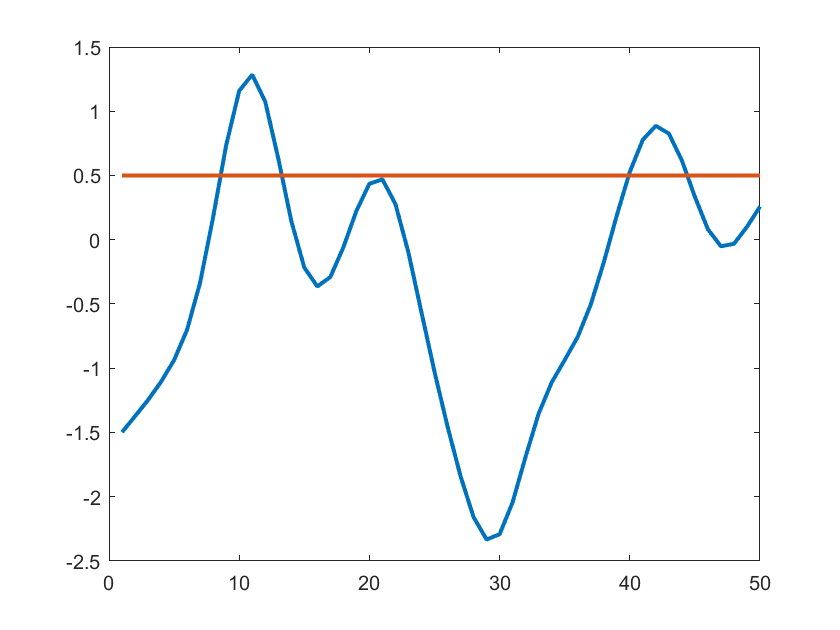

nvox = 50; u = 0.5; FWHM = 6;
smooth_data = noisegen(nvox, 1, FWHM);
clf; plot(1:nvox, smooth_data); hold on
plot(1:nvox, u*ones(1, nvox), 'Linewidth', 2)

clusters = clusterloc_1D(smooth_data', u)

clusters = struct with fields:
               nC: 2
             locs: {2×1 cell}
          indices: {2×1 cell}
           maxloc: [11 42]
           maxval: [1.2847 0.8866]
       peakinclus: [1 1]
          cextent: [5 5]
    edgeindicator: [0 0]
             data: [1×50 double]
            xvals: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50]

clusters.locs{1}

ans =      9    13


Here clusters is an array with information about the clusters. For instance clusters.locs{1} gives start and end locations of the 1st cluster.

#### Stationary Gaussian Convolution Fields

To see how the expected Euler characteristic can be used we show how it can be used to estimate the expected number of clusters in stationary 1D examples.

nvox = 100; niters = 1000; FWHM = 4; spacing = 0.05;
D = 1; numberofclusters = 0; u = 1; padding = round(4*FWHM2sigma(FWHM));
%Note that the padding is needed so that we have a stationary convolution
%field, since this is a stationary example. In general LKCs can be
%calculated under non-stationarity meaning that the edge effect doesn't
%matter.
lat_data = normrnd(0,1,nvox + 2*padding, niters);
field_start_loc = spacep(padding+1, spacing)

field_start_loc = 141

field_end_loc = spacep(padding+nvox, spacing)

field_end_loc = 2121


smoothed_fields = convfield(lat_data, FWHM, spacing, 1);
vareverywhereest = var(smoothed_fields,0,2);
var_est = mean(vareverywhereest(field_start_loc:field_end_loc));
smoothed_fields = smoothed_fields/sqrt(var_est); % To ensure variance 1.

for I = 1:niters
    c_calc = clusterloc_1D(smoothed_fields(field_start_loc:field_end_loc,I)', u);
    numberofclusters = numberofclusters + c_calc.nC;
end
average_number_of_clusters_above_u = numberofclusters/niters

average_number_of_clusters_above_u = 4.1440

Gker_param = FWHM2sigma(FWHM); Lambda_theory = Gker_param^(-2)/2;
L1 = nvox*Lambda_theory^(1/2); L0 = 1;
expectedEC = EEC( u, L1, D, L0, 'gaussian')

expectedEC = 4.1771

As you can see above the expected Euler characteristic perfectly predicts the expected number of clusters! (Note that you should have expected this since the Euler characteristic of an excursion set in 1D is exactly equal to the number of clusters.) Note that decreasing the spacing increases the accuracy of the estimation and vice versa, so it's worth playing around with that parameter above.

In general i.e. high dimensions the cluster approximation is valid even at low thresholds! This because at lots of reasonable threhsolds number of connected components is equal to the Euler charactistic. At high thresholds there is only 0 or 1 cluster (and maximum) above the threshold and so the expected Euler characteristic becomes a very good estimate of the expected number of maxima above the threshold.

#### Old non convolution inference required high smoothing

Equivalently you could do what they did in the old days (aka pre 2020) and use high smoothness! 

nvox = 100; niters = 1000; FWHM = 20;
D = 1; numberofclusters = 0; u = 1;
data = noisegen(nvox, niters, FWHM);
for I = 1:niters
    c_calc = clusterloc_1D(data(:,I)', u);
    numberofclusters = numberofclusters + c_calc.nC;
end
numberofclusters

numberofclusters = 962

average_number_of_clusters_above_u = numberofclusters/niters

average_number_of_clusters_above_u = 0.9620


% Compare to the theoretical prediction:
Gker_param = FWHM2sigma(FWHM);
Lambda_theory = Gker_param^(-2)/2;
L1 = nvox*Lambda_theory^(1/2); L0 = 1;
EEC( u, L1, D, L0, 'gaussian')

ans = 0.9623

However the point of convolution fields is that you can perform inference at any smoothness level. Try setting low FWHM in the example above and see how the estimate for the number of clusters gets worse (when you're not using convolution fields).

### Local Maxima

Local maxima can be found using matlab optimization libraries. To do we need to be able to evaluate the field at every point (not just on a lattice). We need to find local maxima in order to see whether our convolution field has exceeded the threshold at any point.

#### Pointwise evaluation and the importance of truncation

Often you may wish to evaluate your field at a given point rather than everywhere (for instance when searching for local maxima). To do so you can use applyconvfield.m. 

Y = [1,2;3,4];
tval = [1.5,2,4; 3.4,2, 5]; FWHM = 3;
applyconvfield(tval, Y, FWHM)

ans =     0.3594    0.8055    0.0086


This is equivalent to convfield but is quicker if you only want to evaluate the field once rather than on a grid. To show this is equivalent, see below, in practice you'd never do this though if you wanted to evaluate the field on the whole lattice.

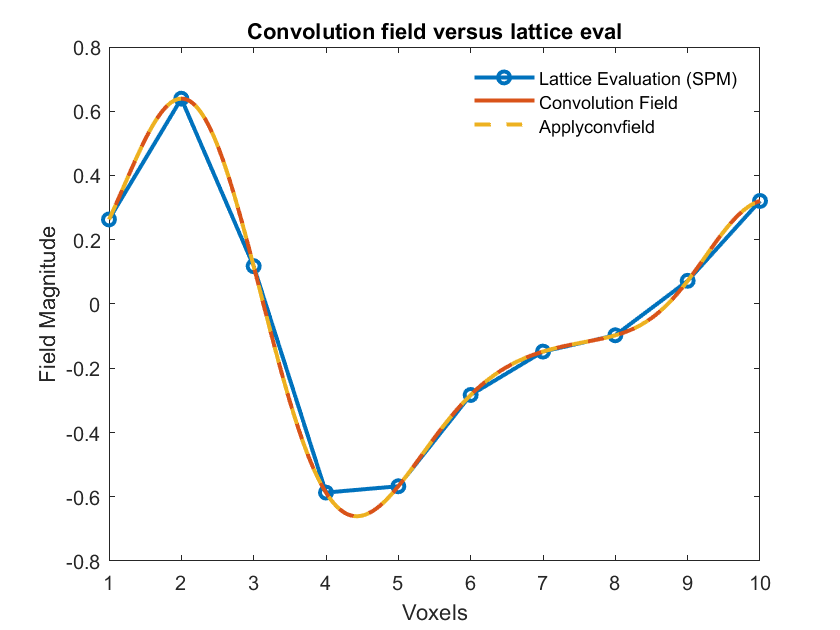

clf; nvox = 10; xvals = 1:nvox; spacing = 0.01;
FWHM = 2; xvals_fine = 1:spacing:nvox;
lat_data = normrnd(0,1,1,nvox);
lattice_field = fconv(lat_data, FWHM);
convolution_field = convfield( lat_data, FWHM, 0.01, 1);
acfield = applyconvfield(xvals_fine, lat_data, FWHM );
plot(xvals, lattice_field, 'o-')
hold on
plot(xvals_fine,convolution_field, '-')
plot(xvals_fine, acfield, '--')
title('Convolution field versus lattice eval')
xlabel('Voxels')
ylabel('Field Magnitude')
legend('Lattice Evaluation (SPM)', 'Convolution Field', 'Applyconvfield')

Computing convolution fields using the full expansion of the Kernel can be quite slow and is unnecessary when the support of your Kernel is small, instead you can truncate the Kernel allowing a large decrease in computational time. 

lat_data = noisegen([91,109,91], 1, 6); FWHM = 3;
ac_notruncation = applyconvfield([50,40,60]', lat_data, FWHM) % No truncation

ac_notruncation = 0.8489

sigma = FWHM2sigma(FWHM); truncation = round(4*sigma);
ac_with_truncation = applyconvfield([50,40,60]', lat_data, FWHM, truncation)

ac_with_truncation = 0.8489

ac_default = applyconvfield([50,40,60]', lat_data, FWHM) %Default

ac_default = 0.8489

Note that by default applyconvfield.m uses a truncation which is 4 times the size of the Kernel parameter. 

#### Finding local maxima

% Fixed lattice values
Y = [1,2,1,1,1,1,2,1]; FWHM = 3;
peak_est_locs = 2;
findconvpeaks(Y, FWHM, 2) % Top 2 peaks

ans =     2.5000    6.5000


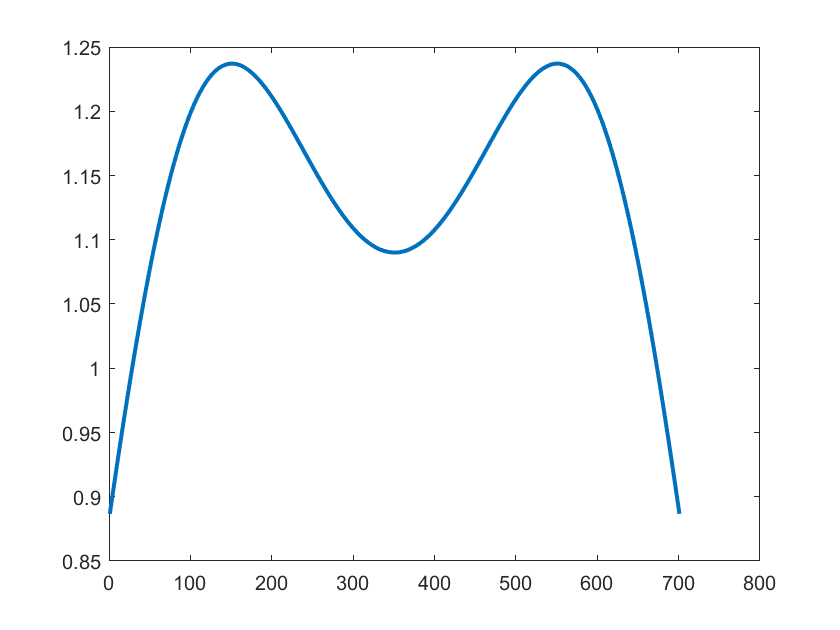

cfield = convfield(Y, FWHM, 0.01, 1);
clf; plot(cfield)

% Random Lattice Values
nvox = 20; FWHM = 4;
lat_data = normrnd(0,1,1,nvox);
findconvpeaks(lat_data, FWHM, 1) % Top peak

ans = 18.9381

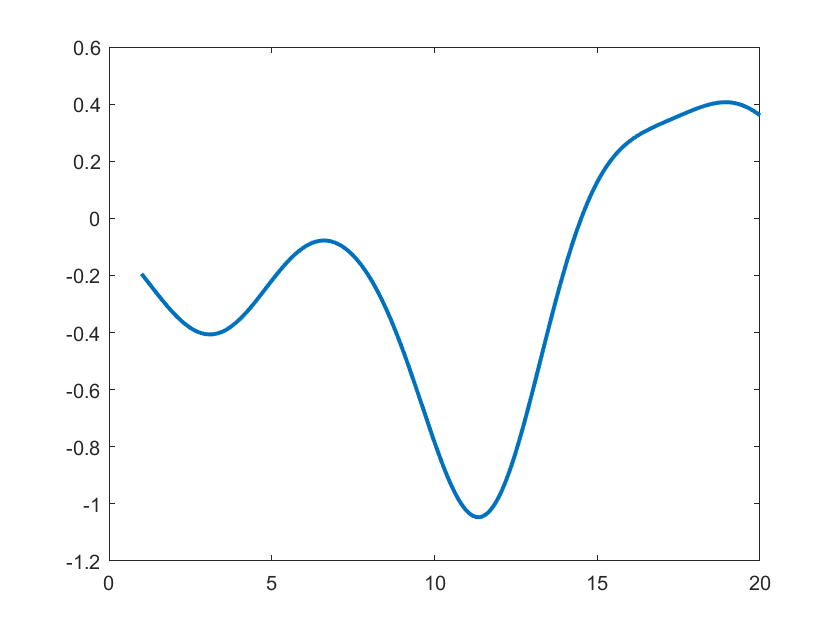

[cfield, xvalsvecs] = convfield(lat_data, FWHM, 0.01, 1);
clf; plot(xvalsvecs{1}, cfield)

### Voxelwise FWER control

In this section we will present some simple examples of using convolution fields to perform voxelwise inference. (The framework is of course more extensive and in general applies to masked images in 3D, something that is a substantially more difficult problem.)

#### Signal generation

In order to demonstrate the use of voxelwise inference to find interesting features of the data (using simulations) we first need a way of generating interesting signal. You may ask why we should smooth in the first place. The following example provides a good illustration of exactly why!

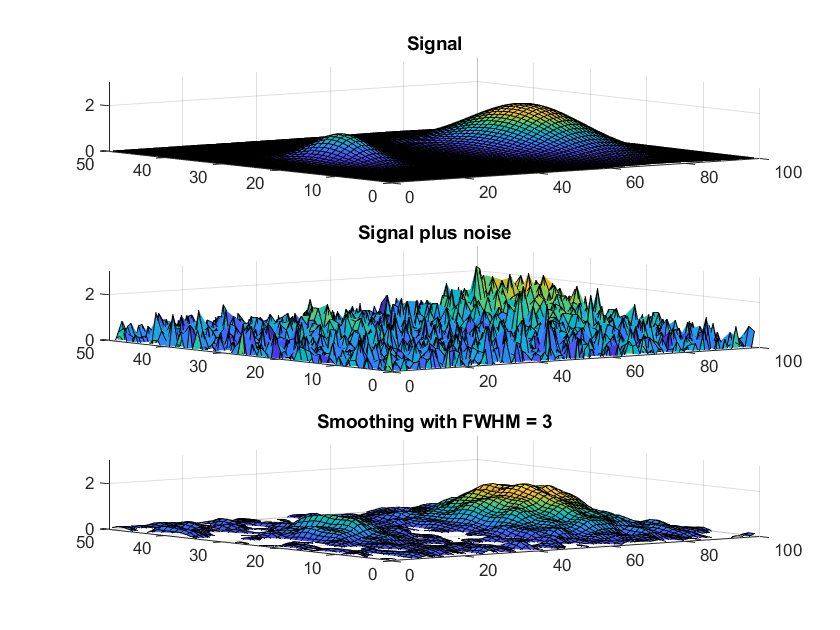

% 2D signal generation
signal_magnitude = [1.2,2];
signal_radii = 3;
smoothnessofpeaks = [10,20];
dimensionofsimulation = [50,100];
peaklocation = {[25,25], [25,75]};

% Data generation
signal = gensig( signal_magnitude, signal_radii, smoothnessofpeaks, ...
    dimensionofsimulation, peaklocation);
noisey_data = randn(dimensionofsimulation)/2 + signal;
FWHM = 3; smoothed_data = fconv(noisey_data, FWHM);

% Plotting
upperlimit = max(noisey_data(:)); zlimits = [0, upperlimit];
clf; subplot(3,1,1); surf(signal); zlim(zlimits); title('Signal')
subplot(3,1,2); surf(mean(noisey_data,3)); 
title('Signal plus noise'); zlim(zlimits)
subplot(3,1,3); surf(mean(smoothed_data,3)); zlim(zlimits)
title(['Smoothing with FWHM = ', num2str(FWHM)])

#### 2D voxelwise inference

This is how you would go about performing voxelwise inference in practice. Feel free to alter the parameters below to test things.

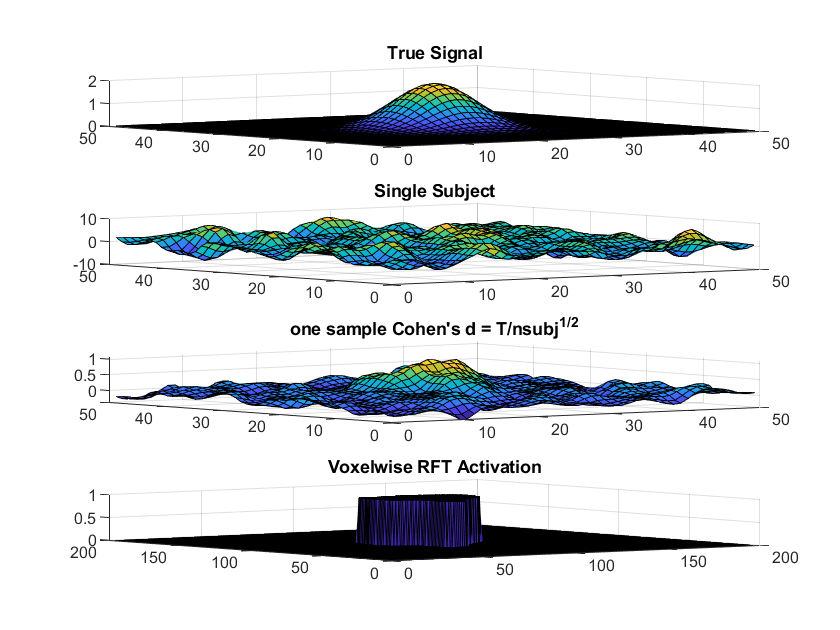

signal_magnitude = 2;
signal_radii = 3;
smoothnessofpeaks = 10;
dimensionofsimulation = [50,50]; 
peaklocation = {[25,25]};

% Data generation
signal = gensig( signal_magnitude, signal_radii, smoothnessofpeaks, ...
    dimensionofsimulation, peaklocation);
nsubj = 75; resAdd = 1;
noisey_data = 10*randn([dimensionofsimulation,nsubj]) + signal;
FWHM = 3; smoothed_data = fconv(noisey_data, FWHM);
% L = LKCestim_GaussConv( noisey_data, FWHM, ones(size(dimensionofsimulation)), resAdd);
[im, threshold] = vRFT( noisey_data, FWHM );

clf; subplot(4,1,1)
surf(signal); title('True Signal')
subplot(4,1,2)
surf(fconv(noisey_data(:,:,1),FWHM));title('Single Subject')
subplot(4,1,3)
surf(smoothtstat(noisey_data, FWHM)/sqrt(nsubj))
title('one sample Cohen''s d = T/nsubj^{1/2}')
subplot(4,1,4)
surf(im); title('Voxelwise RFT Activation')

FYI I'm currently coding a faster version using findconvpeaks_t but have completely finished it yet. Feel free to try other examples (though note that some of the code in beta version still so there are possibly some bugs still).

#### 1D voxelwise validation of RFT (null one-sample t fields)

Here we show how you go about showing that voxelwise inference has the correct coverage rate. 

This is a relatively fast procedure in 1D (but will still take a few minutes), not that in practice you only have to run this once (rather than niters = 1000 times) for inference but here we are checking that we have the correct coverage rates. What takes the longest in the simulations below is the data generation and in practice you will have already gathered your data before running your inference.

% Note this code takes a minute or two to run!
nvox = 20; niters = 1000; FWHM = 2; spacing = 0.1; nsubj = 10;
D = 1; resAdd = 10; pad = 0; alpha = 0.05;

nabovethresh = 0;
nabovethresh_lat = 0;

xvals_fine = 1:spacing:nvox;

for iter = 1:niters
    % Generate data
    lat_field = normrnd(0,1,nvox,nsubj);
    
    % Calculate L1 and the threshold
    L1 = LKCestim_GaussConv( lat_field, FWHM, ones(1,nvox), resAdd);
    
    % calculate the "resel vec for input in SPM"
    % Note that resels are really deprecated, there was never a need
    % to introduce them it turns out so this will soon be replaced
    % in the toolbox.
    resel_vec = [1, L1/sqrt(4*log(2)), 0, 0];
    
    % Calculate the threshold
    threshold = spm_uc_RF(alpha,[1,nsubj-1],'T',resel_vec,1);
    
    % function handle for the convolution t field
    tcf = @(x) tcfield( x, lat_field, FWHM );
    
    % Calculate the t field on a lattice
    tfield_lat = convfield_t(lat_field,FWHM,1);
    
    % calculate the convolution field on a finer lattice
    tfield_fine = convfield_t(lat_field,FWHM,spacing);
    
    % find large local maxima
    high_local_maxima = lmindices(tfield_fine, 3);
    
    % Calculate initial estimates of peak location
    peak_est_locs = [NaN,setdiff(xvals_fine(high_local_maxima),[1,nvox])];
    
    if length(peak_est_locs) == 1
        tfield_at_lms = -Inf; %If the local max occurs at the boundary 
        % you don't need to account for it.
    else
        top_lmlocs = findconvpeaks_t(lat_field, FWHM, peak_est_locs);
        tfield_at_lms = tcf(top_lmlocs);
    end
    
    % Calculate the maximum on the lattice and of the convolution field
    max_lat = max(tfield_lat);
    max_conv = max([tfield_at_lms,max_lat]); %Included for stability 
    % in case the maximum finding didn't work correctly.
    
    if  max_conv > threshold
        nabovethresh = nabovethresh + 1;
    end
    if max_lat > threshold
        nabovethresh_lat = nabovethresh_lat + 1;
    end
    if mod(iter, 50) == 0
        iter %Allows you to monitor the progress
    end
end

iter = 50

iter = 100

iter = 150

iter = 200

iter = 250

iter = 300

iter = 350

iter = 400

iter = 450

iter = 500

iter = 550

iter = 600

iter = 650

iter = 700

iter = 750

iter = 800

iter = 850

iter = 900

iter = 950

iter = 1000

% Note this should be around 0.05.
conv_coverage = nabovethresh/iter 

conv_coverage = 0.0390


%For most runs this will be lower than 0.05. However this effect is
%typically smaller in 1D than in 2D or in 3D.
lat_coverage = nabovethresh_lat/iter

lat_coverage = 0.0300

Note that the difference between the lattice coverage and convolution coverage goes away as the smoothness and/or the number of subjects increases as this makes the data smoother. To see this try taking FWHM = 6 in the above example.